# MATLAB 数学运算

## 矩阵基本运算

### 1-1 矩阵的逆

A = magic(3) % 随机生成3*3矩阵

A =      8     1     6
     3     5     7
     4     9     2



B = inv(A) % 通过inv()求逆

B =     0.1472   -0.1444    0.0639
   -0.0611    0.0222    0.1056
   -0.0194    0.1889   -0.1028


### 1-2 矩阵的特征值与特征向量

A = rand(3,3) % 随机生成3*3矩阵

A =     0.9649    0.9572    0.1419
    0.1576    0.4854    0.4218
    0.9706    0.8003    0.9157


B = eye(3,3) % 生成单位矩阵矩阵

B =      1     0     0
     0     1     0
     0     0     1


d_A = eig(A) % 通过eig()求特征值

d_A =    1.8146 + 0.0000i
   0.2757 + 0.3061i
   0.2757 - 0.3061i


d_B = eig(B)

d_B =      1
     1
     1


## 求解线性方程组 A*X=b

### 2-1 高斯消元法

A = magic(3)

A =      8     1     6
     3     5     7
     4     9     2


C = rand(3,2)

C =     0.7655    0.4898
    0.7952    0.4456
    0.1869    0.6463


b = rand(3,1)

b =     0.7094
    0.7547
    0.2760


X_1 = rref([A b])

X_1 =     1.0000         0         0    0.0131
         0    1.0000         0    0.0026
         0         0    1.0000    0.1004


Y_1 = rref([C b]) % 结果错误

Y_1 =      1     0     0
     0     1     0
     0     0     1


### 2-2 矩阵除法

X_2 = A\b

X_2 =     0.0131
    0.0026
    0.1004


Y_2 = C\b

Y_2 =     0.8277
    0.1852


### 2-3 矩阵求逆

X_3 = inv(A)*b

X_3 =     0.0131
    0.0026
    0.1004


Y_3 = pinv(C)*b

Y_3 =     0.8277
    0.1852


## 多项式运算

### 3-1 

### 𝑝(𝑥) = 𝑥^3 - 4𝑥^2 + 5𝑥 - 2  

p_1 = [1 -4 5 -2] % 定义多项式系数
r_1 = roots(p_1) % 求多项式的根

## 𝑝(𝑥) = 𝑥^5 - 4𝑥^2 - 2  

p_2 = [1 0 0 -4 0 -2]
r_2 = roots(p_2)

### 3-2 conv( )多项式乘运算

## 多项式曲线拟合

### polyfit( )函数来实现多项式的曲线拟合

p = polyfit(x,y,n) % 返回一个n阶多项式的系数数组p。

函数或变量 'x' 无法识别。

y = polyval(p,x) %返回一组数据y满足𝑦 = 𝑝1𝑥^𝑛 + 𝑝2𝑥^𝑛−1 + ⋯ + 𝑝𝑛𝑥 + 𝑝𝑛+1

### 4-1 多项式曲线拟合实例

### Step1:创建x， y作为实验数据

x = 0:0.5:20

x =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000



y = polyval([3,5,1,2],x) + randn(size(x))

y = 1.0e+04 *

    0.0002    0.0006    0.0011    0.0025    0.0047    0.0083    0.0131    0.0196    0.0278    0.0381    0.0509    0.0656    0.0838    0.1044    0.1284    0.1555    0.1865    0.2214    0.2603    0.3033    0.3512    0.4035    0.4611    0.5238    0.5918    0.6656    0.7452    0.8307    0.9228    1.0213    1.1266    1.2391    1.3586    1.4856    1.6204    1.7629    1.9136    2.0728    2.2404    2.4168    2.6021



p_1 = polyfit(x,y,1);
y_1 = polyval(p_1,x);
y_1

y_1 = 1.0e+04 *

   -0.5061   -0.4467   -0.3872   -0.3277   -0.2682   -0.2087   -0.1492   -0.0897   -0.0302    0.0293    0.0888    0.1483    0.2078    0.2673    0.3268    0.3862    0.4457    0.5052    0.5647    0.6242    0.6837    0.7432    0.8027    0.8622    0.9217    0.9812    1.0407    1.1002    1.1597    1.2191    1.2786    1.3381    1.3976    1.4571    1.5166    1.5761    1.6356    1.6951    1.7546    1.8141    1.8736



p_2 = polyfit(x,y,2);
y_2 = polyval(p_2,x);
y_2

y_2 = 1.0e+04 *

    0.1114    0.0782    0.0499    0.0262    0.0073   -0.0068   -0.0162   -0.0208   -0.0207   -0.0158   -0.0062    0.0081    0.0273    0.0511    0.0797    0.1131    0.1512    0.1941    0.2417    0.2941    0.3512    0.4131    0.4797    0.5510    0.6272    0.7080    0.7937    0.8840    0.9791    1.0790    1.1836    1.2930    1.4071    1.5260    1.6496    1.7780    1.9111    2.0490    2.1916    2.3390    2.4911



p_3 = polyfit(x,y,3);
y_3 = polyval(p_3,x);
y_3

y_3 = 1.0e+04 *

    0.0002    0.0005    0.0011    0.0025    0.0048    0.0083    0.0131    0.0195    0.0278    0.0381    0.0507    0.0658    0.0836    0.1044    0.1283    0.1556    0.1866    0.2214    0.2603    0.3035    0.3512    0.4037    0.4611    0.5237    0.5918    0.6655    0.7451    0.8308    0.9228    1.0214    1.1267    1.2391    1.3586    1.4856    1.6203    1.7629    1.9136    2.0727    2.2403    2.4168    2.6022


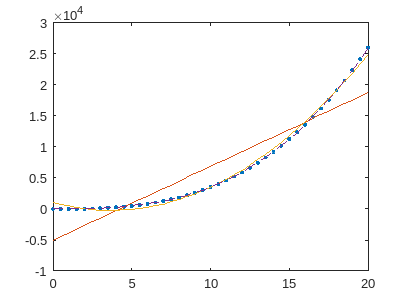


plot(x,y,'.',x,y_1,'-',x,y_2,'-',x,y_3,'--')

## 数据统计

B = [2 5 8 7 4 6 8 4 6 7 5 9 1]

B =      2     5     8     7     4     6     8     4     6     7     5     9     1


y_1 = sum(B) % 求和

y_1 = 72

M_B = mean(B) % 求均值

M_B = 5.5385

S_B = sort(B) % 重新排序

S_B =      1     2     4     4     5     5     6     6     7     7     8     8     9


## 1

A = rand(20,3);
plot(A,'.')
legend('data1','data2','data3')


xstats

xstats = 包含以下字段的 struct :
       min: 1
       max: 20
      mean: 10.5000
    median: 10.5000
      mode: 1
       std: 5.9161
     range: 19


ystats

ystats = 包含以下字段的 struct :
       min: 0.0154
       max: 0.9561
      mean: 0.4347
    median: 0.3968
      mode: 0.0154
       std: 0.3104
     range: 0.9407
